## Cuantificación de la separabilidad

load matlab_clasificacion\data_separ_1.mat

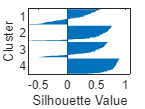

silhouette(X,G)

- La silueta representa lo fácil o difícil que es separar cada una de las observaciones de manera individual teniendo en cuenta la información de pertenencia de clase y las medias de las observaciones de otras clases.

- Teniendo en cuenta lo que se dedujo en la anterior práctica, es coherente pues la cuarta característica se detectaba fácilmente mientras que 1 y 3 presentaban el mayor error.

for i = 1:length(G)
    if s(i) <= 0
        s(i) = 0;
    end
end
s_f = find(s);
X_f = X(s_f,:);
G_f = G(s_f);

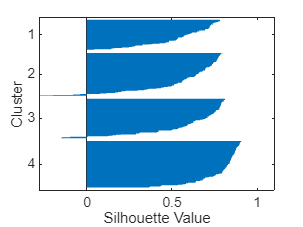

silhouette(X_f,G_f);

- Ha mejorado considerablemente la clasificación. Tras la falta de los elementos que intoxican pues cada núcleo se encuentra mejor definido y se modifican por consiguiente las medias.

N = size(X,1);   
d = size(X,2);    
C = 4;            
n_i = N/C;        
Sw = zeros(d,d);
for i = 1:C
    Xi = X((i-1)*n_i+1 : i*n_i, :);
    Sigma_i = cov(Xi, 1);
    Pi = n_i / N;
    Sw = Sw + Pi * Sigma_i;
end
disp('Matriz de covarianzas intra-clase Sw:')

Matriz de covarianzas intra-clase Sw:


disp(Sw)

    1.7817    1.3205    0.4087
    1.3205    4.5395    0.0858
    0.4087    0.0858    3.0347



Sm = cov(X, 1);
disp('Matriz de covarianzas total Sm:')

Matriz de covarianzas total Sm:


disp(Sm)

   10.8332   -3.3120    0.2163
   -3.3120    7.8971    2.1954
    0.2163    2.1954   11.1011



J1 = trace(Sm) / trace(Sw);
J2 = det(Sm) / det(Sw);
J3 = trace(Sw \ Sm); 
disp('J1 = '), disp(J1)

J1 = 
    3.1885



disp('J2 = '), disp(J2)

J2 = 
   41.5724



disp('J3 = '), disp(J3)

J3 = 
   15.5169



clear all
load matlab_clasificacion\data_separ_2.mat

N = size(X,1);   
d = size(X,2);    
C = 4;            
n_i = N/C;        
Sw = zeros(d,d);
for i = 1:C
    Xi = X((i-1)*n_i+1 : i*n_i, :);
    Sigma_i = cov(Xi, 1);
    Pi = n_i / N;
    Sw = Sw + Pi * Sigma_i;
end
disp('Matriz de covarianzas intra-clase Sw:')

Matriz de covarianzas intra-clase Sw:


disp(Sw)

    0.2747    0.1947    0.0510
    0.1947    0.7558    0.0477
    0.0510    0.0477    0.4582



Sm = cov(X, 1);
disp('Matriz de covarianzas total Sm:')

Matriz de covarianzas total Sm:


disp(Sm)

    8.7625   -4.8149   -0.3055
   -4.8149    4.7064    2.8373
   -0.3055    2.8373    8.6804



J1 = trace(Sm) / trace(Sw);
J2 = det(Sm) / det(Sw);
J3 = trace(Sw \ Sm); 
disp('J1 = '), disp(J1)

J1 = 
   14.8779



disp('J2 = '), disp(J2)

J2 = 
   1.2363e+03



disp('J3 = '), disp(J3)

J3 = 
   77.5539



- Como los índices de separabilidad de la primera muestra evaluada son menores que los de la segunda, significará que son mejor separables las observaciones de la segunda muestra.

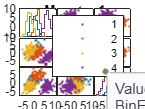

clear all
load matlab_clasificacion\data_separ.mat
gplotmatrix(X,[],G,[]);
title('Muestra 1')

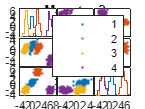

load matlab_clasificacion\data_separ_2.mat
gplotmatrix(X,[],G,[]);
title('Muestra 2')

- Se puede observar claramente que la segunda muestra presenta una mejor separabilidad pues las observaciones pertenecientes a cada clase se encuentran mucho más juntas, además de que los conjuntos de las clases en el espacio de características se presentan más lejanos entre ellos.

- Las mejores clases para implementar en un clasificador de la segunda muestra serían la 4 y la 2. La 1 y la 3 son separables pero puede inducir algo de error.